cellFluoIntensityEvolutionPlot2_ForXjr

% fluoImags = import_tiff_stack('C:\Users\XJY\Desktop\test\sfGFP-1.tif');
% imageMasks  = fluoImCellSeg_ys(fluoImags);

% fluoImags = import_tiff_stack('\\192.168.1.11\e\XJR-shouquan\2020-12-08-xjr-wt-egfp-shouquan\sfGFP.tif');
% 
% imageOut = import_tiff_stack('\\192.168.1.11\e\XJR-shouquan\2020-12-08-xjr-wt-egfp-shouquan\sfGFP-RGB.tif (red).tif');
% 
% imageMasks = imbinarize(imageOut);
% 
% imageTrackings = false(size(imageMasks));
% for i = 1:size(imageMasks,3)
%     image = imageMasks(:,:,i);
%     image = imfill(image,'holes');
%     %     image = image - imageStack(:,:,i);
%     image = imsubtract(image,imageMasks(:,:,i));
%     image = logical(image);
%     imageTrackings(:,:,i) = image;
% end
% 
subregionMasks = false(size(imageMasks));
for i = 1:size(subregionMasks,3)
    subregionMasks(1238:1359,1152:1281,i) = imageTrackings(1238:1359,1152:1281,i) ;
    subregionMasks(:,:,i) = bwareaopen(subregionMasks(:,:,i),80);

end


for iFrame = 1 :size(fluoImags,3)
    stats = regionprops(subregionMasks(:,:,iFrame),fluoImags(:,:,iFrame),...
        'MeanIntensity','MaxIntensity','Centroid');
    cellInfo{iFrame} = stats;
end
f1 = figure,

f1 =   Figure (8) - 属性:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  显示 所有属性


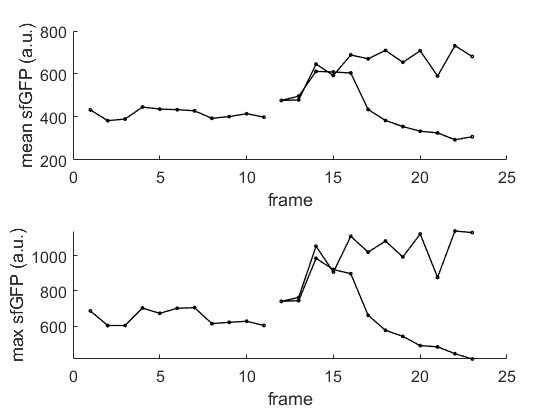


for i = 1:11
    a(i,1) = cellInfo{i}.MeanIntensity; 
    a(i,2) = cellInfo{i}.MaxIntensity; 
end

subplot(2,1,1),
line(1:11,a(:,1),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );

subplot(2,1,2),
line(1:11,a(:,2),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );

for i = 12:23
    b(i,1:2) = [cellInfo{i}.MeanIntensity]; 
    b(i,3:4) = [cellInfo{i}.MaxIntensity]; 
end
subplot(2,1,1),
line(12:23,b(12:23,1),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );
line(12:23,b(12:23,2),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );
subplot(2,1,2),
line(12:23,b(12:23,3),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );
line(12:23,b(12:23,4),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );


subplot1 = subplot(2,1,1,'Parent',f1);
hold(subplot1,'on')
set(subplot1,'FontSize',12);
box(subplot1,'off');
% legend(subplot1,'show');
hold(subplot1,'off')
ylabel({'mean sfGFP (a.u.)'});
xlabel({'frame'});


subplot2 = subplot(2,1,2,'Parent',f1);
hold(subplot2,'on')
set(subplot2,'FontSize',12);
box(subplot2,'off');
% legend(subplot2,'show');
hold(subplot2,'off')
ylabel({'max sfGFP (a.u.)'});
xlabel({'frame'});